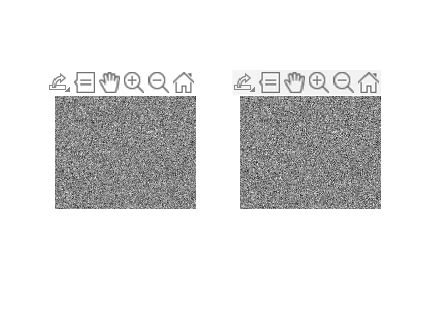

clear
clc

load('snow.mat');
[ACstream, DCstream, h, w] = JpegEncoder(snow);
Image_Decoded = JpegDecoder(DCstream,ACstream,h,w);
subplot(1,2,1);
imshow(snow);
title('Original');
subplot(1,2,2);
imshow(Image_Decoded);
title('Compressed');

计算PSNR

MSE = sum((Image_Decoded-snow).^2,'all')/h/w;
PSNR = 10 * log10(255^2/MSE);

PSNR = 29.5614

计算压缩比

compressrate = 8*h*w/(length(ACstream)+length(DCstream));

compressrate = 3.6450